#### Definición de los parámetros del sistema

Este primer bloque de código genera una señal aleatoria de un determinado tamaño. También se generan los ejes de tiempo y frecuencia para su representación.

clear; close all, format compact

NFFT  = 128;            % Longitud FFT [muestras]
Fs    =	1e5;            % Frecuencia de muestreo [Hz] [simbolos/segundo]
Ts    = 1/Fs;           % Tiempo de muestreo [s] [segundo/simbolo]
Nsym  = 32;             % Numero de simbolos [simbolos]
m     =	16;             % Orden de modulacion 
b     = log2(m);        % Bits por simbolo [bits/simbolo]
Nbits = Nsym*b;         % Numero total de bits en la señal

x = round(rand(1,Nbits));
t = linspace(0,Ts,Nbits);
X = fftshift(fft(x,NFFT));
f = Fs/NFFT*(-NFFT/2:NFFT/2-1);

#### Representación temporal señal aleatoria

A continuación se muestra la señal generada de forma aleatoria.

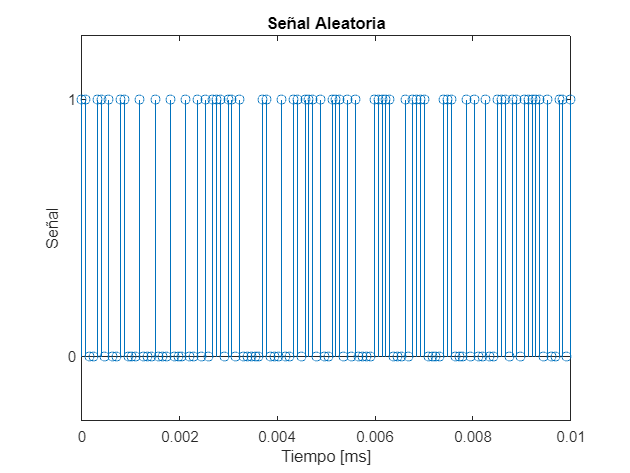

figure;
grid on;
stem(t*1e3,x);
title("Señal Aleatoria")
xlabel("Tiempo [ms]")
ylabel("Señal")
yticks([0 1])
yticklabels({'0','1'})
ylim([-0.25 1.25])

#### Representación espectral señal aleatoria

En esta siguiente figura se muestra el módulo y fase del espectro de la señal aleatoria.

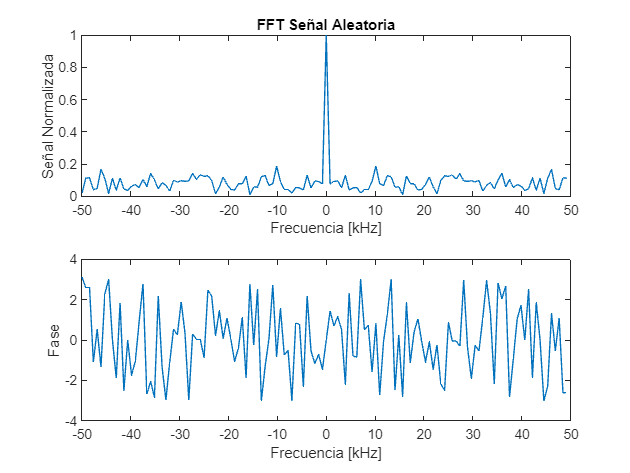

figure;
subplot(2,1,1);
grid on;
plot(f/1e3,abs(X)/max(abs(X)));
title("FFT Señal Aleatoria")
xlabel("Frecuencia [kHz]")
ylabel("Señal Normalizada")
subplot(2,1,2);
grid on;
plot(f/1e3,angle(X));
xlabel("Frecuencia [kHz]")
ylabel("Fase")

#### Representación de la respuesta al impulso del canal

El canal utilizado se muestra en la siguiente figura.

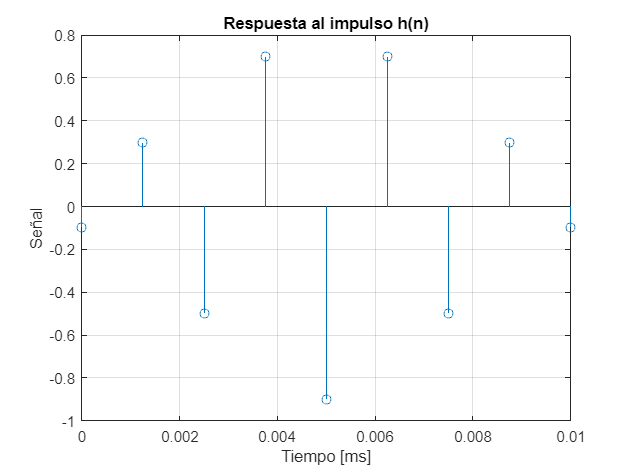

h = [-0.1,0.3,-0.5,0.7,-0.9,0.7,-0.5,0.3,-0.1];
t = linspace(0,Ts,length(h));
H = fftshift(fft(h,NFFT));
f = Fs/NFFT*(-NFFT/2:NFFT/2-1);

figure;
stem(t*1e3,h);
title("Respuesta al impulso h(n)")
xlabel("Tiempo [ms]")
ylabel("Señal")
grid on;

#### Representación espectral de la respuesta al canal

Como se puede observar en la siguiente figura donde se muestra el módulo y la fase por separado, el canal presenta una respuesta en fase lineal, por lo que no se producirá distorsión a la salida. Además este canal cumple las condiciones de Nyquist para cero ISI.

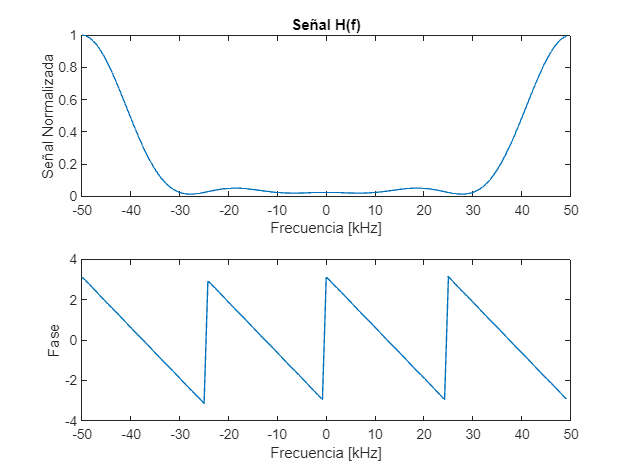

figure;
subplot(2,1,1)
grid on;
plot(f/1e3,abs(H)/max(abs(H)));
title("Señal H(f)")
xlabel("Frecuencia [kHz]")
ylabel("Señal Normalizada")
xlim([-Fs/2e3 Fs/2e3])
subplot(2,1,2);
grid on;
plot(f/1e3,angle(H));
xlabel("Frecuencia [kHz]")
ylabel("Fase")

#### Representación espectral convolución lineal y convolución circular

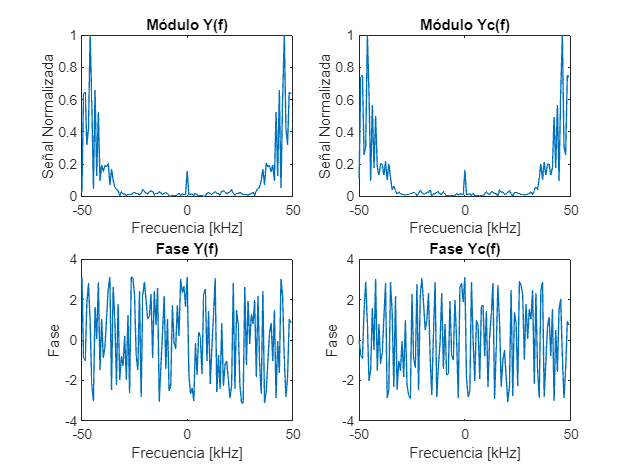

y = conv(x,h);
Y = fftshift(fft(y,NFFT));

N = max(length(x),length(h));
yc = cconv(x,h,N);
Yc = fftshift(fft(yc,NFFT));

error1 = sum(abs(X.*H-Y));
error2 = sum(abs(X.*H-Yc));

figure;
subplot(2,2,1);
plot(f/1e3,abs(Y)/max(abs(Y)));
title("Módulo Y(f)")
xlabel("Frecuencia [kHz]")
ylabel("Señal Normalizada")
xlim([-Fs/2e3 Fs/2e3])
subplot(2,2,3);
plot(f/1e3,angle(Y));
title("Fase Y(f)")
xlabel("Frecuencia [kHz]")
ylabel("Fase")
subplot(2,2,2)
plot(f/1e3,abs(Yc)/max(abs(Yc)));
title("Módulo Yc(f)")
xlabel("Frecuencia [kHz]")
ylabel("Señal Normalizada")
xlim([-Fs/2e3 Fs/2e3])
subplot(2,2,4);
plot(f/1e3,angle(Yc));
title("Fase Yc(f)")
xlabel("Frecuencia [kHz]")
ylabel("Fase")

En módulo no se aprecia mucha diferencia, sin embargo en la fase las diferencias son notables.

#### Demostración multiplicación espectros

disp(['Error X*H = Y: ',num2str(error1)])

Error X*H = Y: 154.0203


disp(['Error X*H = Yc: ',num2str(error2)])

Error X*H = Yc: 2.7317e-13


Esto demuestra que la multiplicación de los espectros de la señal entrante y el canal es igual al resultado de la convolución circular.

#### Adición de prefijo cíclico

La longitud del prefijo cíclico debe ser igual o superior a la longitud del canal para que en caso de ISI este afecte solo al prefijo de guardia. Siendo $N$ la longitud de la señal entrante y $L$ la longitud del canal, la longitud del prefijo cíclico escogida es $L$ o superior. Se toman las últimas muestras de la señal $x\left(t\right)$, desde $N-L+1$ a $N$. Para extraer el prefijo cíclico de la señal, se toman solamente las muestras desde $L+1$ hasta el final de la señal.

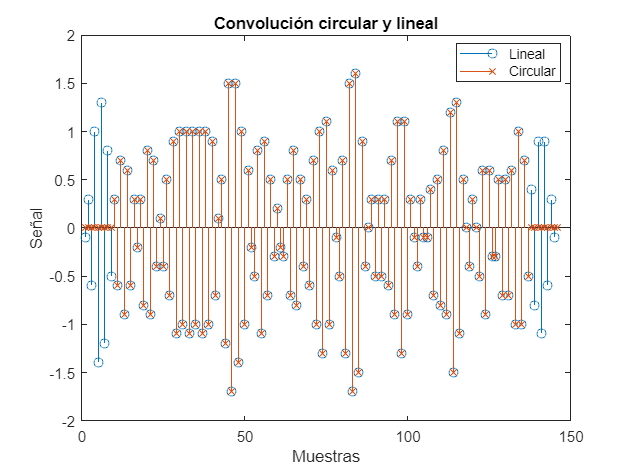

L = length(h);
N = length(x);

% Convolución circular
N = max(length(x),length(h));
yc = cconv(x,h,N);

% Adición del prefijo cíclico
cp = x(N-L+1:N);
x_cp = [cp x];

% Convolución con el canal
y = conv(x_cp,h);
pad = zeros(1,length(h));
yc = [pad yc pad];

figure;
grid on;
stem(y,'o');
hold on;
stem(yc,'x');
title("Convolución circular y lineal")
xlabel("Muestras")
ylabel("Señal")
legend('Lineal','Circular','location','best')

### 2º Ecualización

Un ecualizador modifica el nivel de contenido o peso en frecuencias o *bins *de la señal procesada. Solmanet emodifica la amplitud de la componente espectral. El objetivo es tratar de *invertir *los efectos del canal. En un caso real, donde el canal es desconocido y debe ser estimado, son utilizadas posiciones especiales en frecuencia donde viajan componentes piloto, cuyo valor es conocido por el equipo receptor por estándar, como en el caso de la señal DVB-T que utiliza pilotos y subpilotos en sus diferentes símbolos OFDM cuya posición es fija.

Se van a evaluar tres casos diferentes de prefijo de guardia o circular.

- Prefijo todo a cero de longitud superior al canal (16 muestras de longitud)

- Prefijo cíclico de longitud inferior al canal (4 muestras)

- Prefijo cíclico de longitud superior al canal (16 muestras)

clear;

NFFT  =	128;            % Tamaño de la FFT. Para mayor velocidad debe ser múltiplo de dos
df    = 200;            % Separación entre portadoras
Fs    =	25600;          % Frecuencia de muestreo
Nf    =	10;             % Numero de portadoras con datos
m_ary =	4;              % Indicador de modulacion digital de cada portadora
Nofdm = 100;            % Número de símbolos OFDM

Nbits = Nofdm*Nf*log2(m_ary);   % Número de bits a transmitir
txbits = round(rand(1,Nbits));  % Generación bits aleatorios
xmod = moduladorQPSK(txbits);

% Caso 1
ydemod1 = eq_zeros(txbits,16,NFFT,Nf,Nofdm);

% Caso 2
ydemod2 = eq_cp(txbits,4,NFFT,Nf,Nofdm);

% Caso 3
ydemod3 = eq_cp(txbits,16,NFFT,Nf,Nofdm);

#### Representación señal QPSK transmitida

Se muestra la constelación QPSK transmitida.

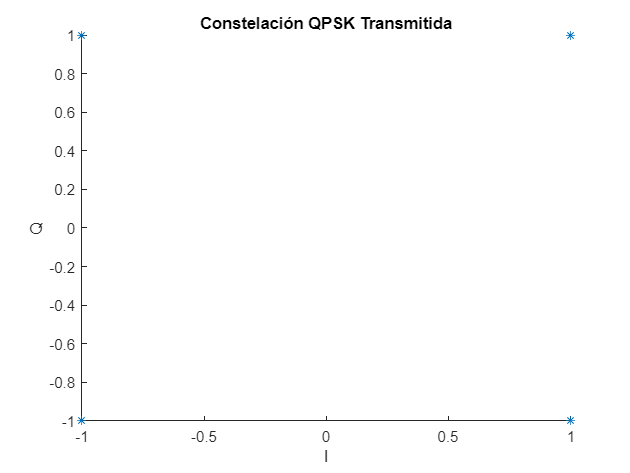

figure;
scatter(real(xmod),imag(xmod),'*');
title('Constelación QPSK Transmitida');
xlabel("I");
ylabel("Q");

#### Primer Caso. Prefijo todo a cero de longitud superior al canal.

En este caso, se observa cierto error en la constelación de salida, esto es debido a utilizar un prefijo de solamente ceros, sin ningún tipo de redundancia. Sin embargo, al ser su longitud superior a la del canal, la demodulación final no presentará interferencia entre símbolos.

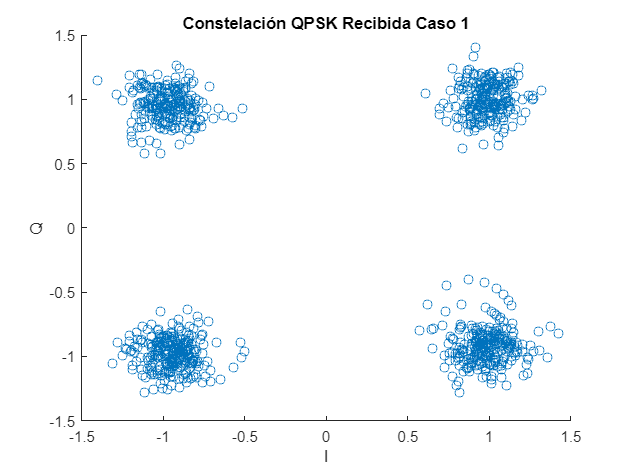

figure;
scatter(real(ydemod1),imag(ydemod1));
title('Constelación QPSK Recibida Caso 1');
xlabel("I");
ylabel("Q");

#### Segundo Caso. Prefijo cíclico de longitud inferior al canal.

Este caso demuestra que utilziar un prefijo cíclico de longitud inferior al canal,ya sea una ristra de ceros o un prefijo cíclico en sí, no es capaz de evita errores en detección.  Este caso presenta interferencia entre símbolos.

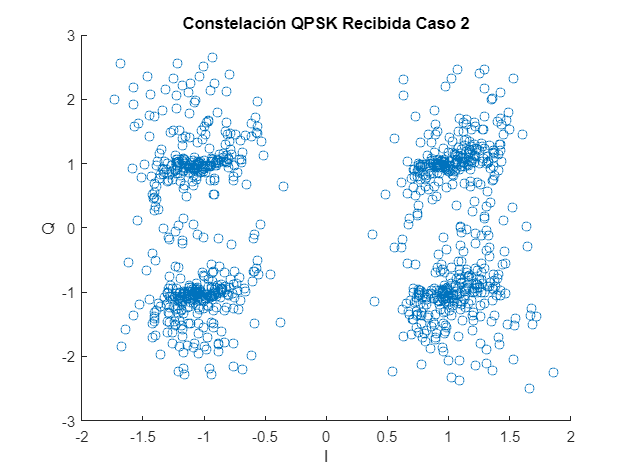

figure;
scatter(real(ydemod2),imag(ydemod2));
title('Constelación QPSK Recibida Caso 2');
xlabel("I");
ylabel("Q");

#### Tercer Caso. Prefijo cíclico de longitud superior al canal.

Utilizar un prefijo cíclico superior a la longitud del canal elimina la posible interferencia entre sñimbolos y por tanto se obtiene una constelación QPSK en recepción my satisfactoria.

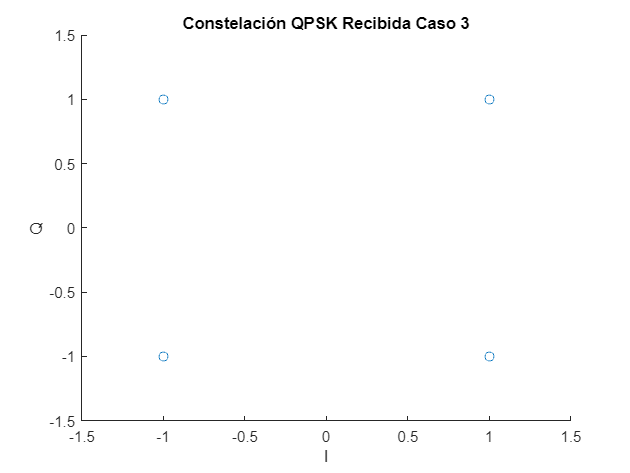

figure;
scatter(real(ydemod3),imag(ydemod3));
title('Constelación QPSK Recibida Caso 3');
xlabel("I");
ylabel("Q");

La ecualización no deja de ser una dividión entre la señal recibida y una estimación del canal, ya que este en aplicaciones reales no suele ser conocido y debe ser estimado. Algunas mejoras que se pueden realizar este proceso son las siguientes.

- Si el canal es desconocido, utilizar portadoras piloto cuya posición y valores son conocidos creando una primera estimación del canal incompleta, esta es posteriormente interpolada para completarla.

- Si el canal es conocido, incrementar la longitud de la FFT y por tanto aumentar la longitud útil (longitud de símbolo sin prefijo cíclico).

#### USO DE PILOTOS

Con el objetivo de aproximar este ejemplo al mundo real, para generar los pilotos en la señal y sus posiciones se emplea una adaptación del estándar DVB-T, donde se emplea una secuencia pseudoaleatoria para generar las posiciones. En primer lugar se genera la señal OFDM y se introducen tanto portadoras con datos como portadoras piloto.

NFFT  =	8192;                   % Tamaño de la FFT. Para mayor velocidad debe ser múltiplo de dos
Nf    =	10;                     % Numero de portadoras con datos
m_ary =	4;                      % Indicador de modulacion digital de cada portadora
Nofdm = 128;                    % Número de símbolos OFDM
l_cp  = NFFT*1/32;              % Longitud prefijo cíclico
pilot = 1:4:28;                 % Posiciones portadoras piloto

wk = prbs_dvbt(NFFT);                           % Secuencia pseudoaleatoria PRBS
Nbits = Nofdm*Nf*log2(m_ary);                   % Número de bits a transmitir
txbits = round(rand(1,Nbits));                  % Generación bits aleatorios
pilot_inf = zeros(1,NFFT);                      % Allocating pilotos
pilot_inf(:,pilot) = (4/3)*2*(0.5-wk(pilot));   % Generación pilotos estándar DVB-T

h = [-0.1,0.3,-0.5,0.7,-0.9,0.7,-0.5,0.3,-0.1];

xmod = moduladorQPSK(txbits);
X = repmat(pilot_inf.',1,Nofdm);
X(29:38,:) = reshape(xmod,Nf,Nofdm);
X = X + flipud(conj(X));
x = ifft(X, NFFT,'symmetric')*NFFT;
cp = zeros(l_cp,Nofdm);
x = [cp ; x];
s = reshape(x,1,Nofdm*(l_cp+NFFT));

A continuación se convoluciona la señal con la respuesta al impulso del canal para simular su transmisión y consecuente modificación.

s_rx = conv(s,h);
s_rx = s_rx(1:end-length(h)+1);

En recepción, se recompone la señal en forma de matriz y se retira el prefijo cíclico.

x_cp_rx = reshape(s_rx, NFFT+l_cp, Nofdm);
x_rx = x_cp_rx(l_cp+1:end,:);

Finalmente se da el proceso de ecualización. En primer lugar se realiza la demodulación OFDM de la señal a partir de la FFT. Los pasos para realizar la ecualización son los siguientes.

- Preparación de los valores de portadoras e índices. Por estándar estos valores son conocidos.

- Estimación del canal incompleta a partir de los pilotos presentes en la señal.

- Interpolación de la respuesta del canal con el objetivo de terminar de completar la respuesta en frecuencia estimada. Se realiza la interpolación para obtener una respuesta al canal de la misma longitud que el símbolo útil.

% Demodulación OFDM
X_RX = fft(x_rx,NFFT)/NFFT;

% Posiciones pilotos teniendo en cuenta la conjugada
carriers = [pilot NFFT-max(pilot):4:NFFT];

% Valores pilotos teniendo en cuenta la conjugada
pilot_inf(NFFT-max(pilot):4:NFFT) = pilot_inf(pilot(1):4:pilot(end));

% Estimación del canal en las posiciones de las portadoras piloto
H(carriers) = X_RX(carriers)/pilot_inf(carriers);

% Interpolación para completar la respuesta al canal
carriers = find(abs(H)~=0);
H = interp1(carriers,H(carriers),1:NFFT,'linear','extrap');

% Ecualización
X_RX_EQ = X_RX ./ repmat(2*H.',1,Nofdm);

Como en ocasiones anteriores, el último paso consiste en extraer las portadoras de datos y mostrar la constelación obtenida. Como se puede observar en la constelación de símbolos obtenida, se aprecia cierto error de fase, ya que la constelación se encuentra ligeramente girada respecto a las coordenadas originales. Esto es debido al propio proceso de estimación, puesto que el canal estimado nunca será una versión idéntica al canal real, es posible mejorar esta estimación empleando un mayor número de pilotos o utilizando técnicas como los mínimos cuadrados.

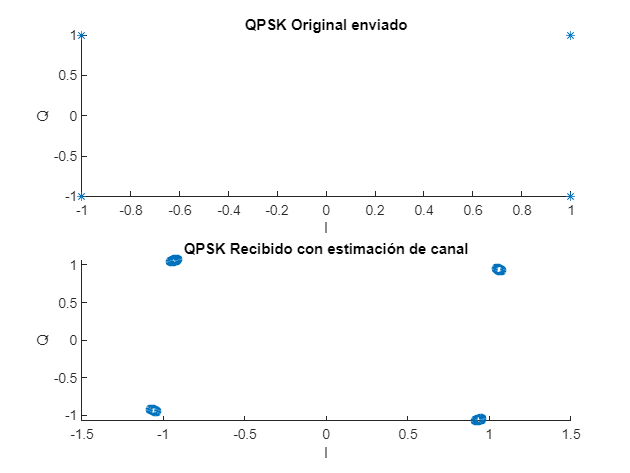

ydemod = X_RX_EQ(29:38,:);
ydemod = (reshape(ydemod,1,Nf*Nofdm)).';

figure;
subplot(2,1,1);
scatter(real(xmod),imag(xmod),"*");
title("QPSK Original enviado")
xlabel("I")
ylabel("Q")
subplot(2,1,2);
scatter(real(ydemod),imag(ydemod));
title("QPSK Recibido con estimación de canal")
xlabel("I")
ylabel("Q")

Esta operación de estimación de canal a partir de portadoras piloto e interpolación es utilizada en sistemas de RADAR pasivo con un único canal de recepción. Al poseer un único canal, en este mismo se reciben dos señales de interés, la señal del iluminador de oportunidad (emisor) y la señal de eco o "rebote" proveniente del objetivo. La idea principal consiste en demodular ambas señales a partir de la ecualización y demodulación de ambas.

#### MODIFICACIÓN DE LA LONGITUD DE SÍMBOLO ÚTIL

Otra posible opción para mejorar el resultado de la ecualización es el aumento de la longitud de la FFT. Si el canal es conocido, aumentar la longitud de la FFT aumentará drásticamente la resolución obtenida en la constelación QPSK resultante. Esto es debido a que la operación de ecualización ofrece un mejor resultado a mayor número de puntos introducidos. Aumentando la longitud de la FFT se aumenta el número de puntos en los símbolos OFDM recibidos y el tamaño de la FFT de la respuesta al impulso del canal, por tanto la señal resultante de la ecualización posee más información sobre la señal transmitida, minimizando el error en detección.

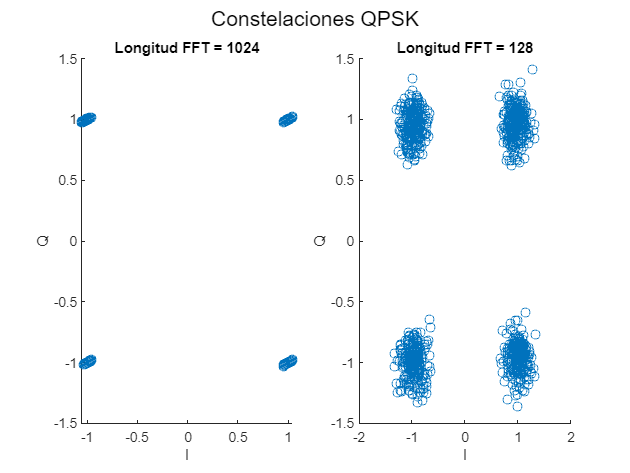

Nf    =	10;             % Numero de portadoras con datos
m_ary =	4;              % Indicador de modulacion digital de cada portadora
Nofdm = 100;            % Número de símbolos OFDM

Nbits = Nofdm*Nf*log2(m_ary);   % Número de bits a transmitir
txbits = round(rand(1,Nbits));  % Generación bits aleatorios
xmod = moduladorQPSK(txbits);   % Modulación QPSK

% Dos casos donde solamente varia la longitud de la FFT
ydemod1 = eq_zeros(txbits,16,1024,Nf,Nofdm);
ydemod2 = eq_zeros(txbits,16,128,Nf,Nofdm);

figure;
sgtitle("Constelaciones QPSK")
subplot(1,2,1);
scatter(real(ydemod1),imag(ydemod1));
title("Longitud FFT = 1024")
xlabel("I")
ylabel("Q")

subplot(1,2,2);
scatter(real(ydemod2),imag(ydemod2));
title("Longitud FFT = 128")
xlabel("I")
ylabel("Q")

## FUNCIONES UTILIZADAS

function xMod = moduladorQPSK(txBits)
%%
%  Esta función genera una señal modulada en QPSK en función de un vector de parejas de bits
%
% txBits    vector fila de bits de entrada. Su longitud debe ser par
% xMod      vector fila de símbolos modulados en QPSK en banda base. 
%           Sus elementos son números complejos y su longitud la mitad de la de txbits
%
% Comprobación de que la longitud de txBits es par
  n = length(txBits);
  if rem(n,2)~ 0;
      error('La longitud de txBits no es par');
  end
%
% Copia de txBits a vector fila
  b = txBits(:)';
%
% Se generan los vectores I (fase) y Q (cuadratura)
% Los 1s se asimilan a fase 0 (+1) y los 0s a fase pi (-1)
  b = (reshape(b', 2, n/2) - 0.5)*2;
  I = b(1,:);
  Q = b(2,:);
%
% Se genera la señal modulada como suma de señales BPSK en fase y cuadratura
  xMod = I + j*Q;
 %
end

function rxBits = demoduladorQPSK(rxSimbol)
%%
%  Esta función demodula una señal QPSK en banda base, contenida en el vector de entrada rxSimbol
%
% rxSimbol  vector fila de símbolos de entrada. 
% xmod      vector fila de bits resultado de demodular. Su longitud el doble de la de rxSimbol
%
% Inicialización
  n = length(rxSimbol);
  rxBits = zeros(1, 2*n);
%
% Copia de rxSimbol a vector fila
  b = rxSimbol(:).';
%
% Se generan los vectores I (fase) y Q (cuadratura) 
%
  I   = zeros(1,n);
  ind = find(real(b)>=0);
  I(ind) = 1;
  Q   = zeros(1,n);
  ind = find(imag(b)>=0); 
  Q(ind) = 1;
%
% Se genera el vector de bits en base a I y Q
  rxBits = reshape([I ; Q], 1, 2*n); 
%
end

function ydemod = eq_cp(txbits,l_cp,NFFT,Nf,Nofdm)
    h = [-0.1,0.3,-0.5,0.7,-0.9,0.7,-0.5,0.3,-0.1];
    % Modulación QPSK
    xmod = moduladorQPSK(txbits);
    % Modulación OFDM
    X = zeros(NFFT, Nofdm);
    
    X(29:38,:) = reshape(xmod,[Nf,Nofdm]);
    X = X + flipud(conj(X));
    x = ifft(X, NFFT,'symmetric')*NFFT;
    
    cp = x(end-l_cp+1:end,:);

    x = [cp ; x];
    s = reshape(x,1,Nofdm*(l_cp+NFFT));

    s_rx = conv(s,h);
    s_rx = s_rx(1:end-length(h)+1);
    
    x_cp_rx = reshape(s_rx, NFFT+l_cp, Nofdm);
    x_rx = x_cp_rx(l_cp+1:end,:);
    X_RX = fft(x_rx,NFFT)/NFFT;
    
    H = fft(h,NFFT);
    X_RX_EQ = X_RX ./ repmat(H.',1,Nofdm);
    
    ydemod = X_RX_EQ(29:38,:);
    ydemod = (reshape(ydemod,1,Nf*Nofdm)).';
end

function ydemod = eq_zeros(txbits,l_cp,NFFT,Nf,Nofdm)
    h = [-0.1,0.3,-0.5,0.7,-0.9,0.7,-0.5,0.3,-0.1];
    % Modulación QPSK
    xmod = moduladorQPSK(txbits);
    % Modulación OFDM
    X = zeros(NFFT, Nofdm);
    
    X(29:38,:) = reshape(xmod,Nf,Nofdm);
    X = X + flipud(conj(X));
    x = ifft(X, NFFT,'symmetric')*NFFT;
    
    cp = zeros(l_cp,Nofdm);

    x = [cp ; x];
    s = reshape(x,1,Nofdm*(l_cp+NFFT));
    s_rx = conv(s,h);
    s_rx = s_rx(1:end-length(h)+1);
    
    x_cp_rx = reshape(s_rx, NFFT+l_cp, Nofdm);
    x_rx = x_cp_rx(l_cp+1:end,:);
    X_RX = fft(x_rx,NFFT)/NFFT;
    
    H = fft(h,NFFT);
    X_RX_EQ = X_RX ./ repmat(H.',1,Nofdm);
    
    ydemod = X_RX_EQ(29:38,:);
    ydemod = (reshape(ydemod,1,Nf*Nofdm)).';
end

function [wk] = prbs_dvbt(len_seq)
    wk = zeros(1,len_seq);
    mem = (ones(1,11));
    for i = 1:len_seq
        wk(i) = mem(1);
        mem(:) = [mem(2:end) bitxor(mem(1),mem(3))];
    end
end